# **RS-EO-05-01 Satellite Network Design**

**UT Austin ASE**

**Hongseok Kim**

**10/19/2024**

## I. Load Constellation 

clear;
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_01_Constellation_Initialization/');
load('constellation_setting.mat')

## II. 1Add Receiving Ground Station

elevation_angle_condition = 15;

receiving_gs_info = ["Svalbard, Norway", 78.2300, 15.4100, 120;
                     "Alaska Satellite Facility, USA", 64.8581, -147.8494, 133;
                     "King Sejong Station, Antarctica", -62.2233, -58.7855, 11;
                     "Troll Station, Antarctica", -72.0167, 2.5333, 1275;
                     "McMurdo Station, Antarctica", -77.8419, 166.6863, 24;
                     "Tromsø, Norway", 69.6492, 18.9560, 10;
                     "Inuvik, Canada", 68.3600, -133.7236, 65;
                     "Prince Albert, Canada", 53.2022, -105.7453, 428;
                     "Wallops Island, Virginia, USA", 37.9402, -75.4661, 14;
                     "Santiago, Chile", -33.4489, -70.6693, 520;
                     "Hartebeesthoek, South Africa", -25.8870, 27.7044, 1415;
                     "Dongara, Australia", -29.2049, 114.9389, 20];


gs = groundStation(scenario,"Name",receiving_gs_info(:,1), ...
                        "Latitude",str2double(receiving_gs_info(:,2)), ...
                        "Longitude", str2double(receiving_gs_info(:,3)), ...
                        "Altitude", str2double(receiving_gs_info(:,4)), ...
                        "MinElevationAngle", elevation_angle_condition ...
                        );

## III. Create Sat-to-Sat / Sat-to-GS Contact Matrix

list_of_Satellites = scenario.Satellites;
no_of_satellites = length(list_of_Satellites);
no_of_receiving_gs = length(receiving_gs_info(:,1));
no_of_timesteps = seconds(scenario.StopTime - scenario.StartTime)/scenario.SampleTime +1;

% define satelite to satellite contact matrix
sat_to_sat_contact_matrix = zeros(no_of_satellites, no_of_satellites, no_of_timesteps);

### III.1 Mode 1: Access By visibility

% ac_between_orbit = access(list_of_Satellites(1:45),list_of_Satellites(16:60));
% ac_between_orbit.LineColor = 'g';

% % 주어진 인덱스 배열
% index_order = 16:60;
% 
% % 패턴에 맞춰 1로 설정
% for i = 1:45
%     j = index_order(i);  % 해당 인덱스 배열에서 순서대로 선택
%     sat_to_sat_contact_matrix(i, j, :) = 1;
% end

### **III.2 Mode 2: Access By Laser Coms Viewangle**

list_of_COMS_payload = scenario.Satellites.ConicalSensors;
laser_coms_1_vector = list_of_COMS_payload(1:2:119);
laser_coms_2_vector = list_of_COMS_payload(2:2:120);

ac_between_orbit_1 = access(laser_coms_1_vector(1:45), laser_coms_2_vector(16:60));
ac_between_orbit_1.LineColor = 'g';
ac_between_orbit_2 = access(laser_coms_2_vector(1:45), laser_coms_1_vector(16:60));
ac_between_orbit_1.LineColor = 'g';


ac_status_between_orbit = accessStatus(ac_between_orbit_1) + accessStatus(ac_between_orbit_2);

index_order = 16:60;

for i = 1:45
    j = index_order(i);  % 해당 인덱스 배열에서 순서대로 선택
    sat_to_sat_contact_matrix(i, j, :) = ac_status_between_orbit(i,:);
end

### III.3 Inside Orbit Communication


ac_inside_orbit = access(list_of_Satellites(1:60),list_of_Satellites([2:15, 1, 17:30, 16, 32:45, 31, 47:60, 46]));
ac_inside_orbit.LineColor = 'b';

% 주어진 인덱스 배열
index_order = [2:15, 1, 17:30, 16, 32:45, 31, 47:60, 46];

% 패턴에 맞춰 1로 설정
for i = 1:60
    j = index_order(i);  % 해당 인덱스 배열에서 순서대로 선택
    sat_to_sat_contact_matrix(i, j, :) = 1;
end


### III.4 Define Satellite to GS contact

sat_to_gs_contact_matrix = zeros(no_of_satellites, no_of_receiving_gs, no_of_timesteps);

for index = 1:no_of_receiving_gs
    sat_to_gs_temp = access(list_of_Satellites, gs(index));
    sat_to_gs_temp.LineColor = 'r';
    sat_to_gs_contact_matrix(:,index,:) = accessStatus(sat_to_gs_temp);
end


% play(scenario)

## V. Plot Graph and Nodes

numGroundStations = length(receiving_gs_info(:,1));
numSatellites = length(list_of_Satellites);
time_index  = 100;

gs_to_sat_contact_matrix = permute(sat_to_gs_contact_matrix, [2, 1, 3]);
GS_to_Sat = gs_to_sat_contact_matrix(:,:,time_index);
Sat_to_Sat = sat_to_sat_contact_matrix(:,:,time_index);

% Create a graph object
G = graph();

% Add Ground Stations as nodes
for i = 1:numGroundStations
    G = addnode(G, sprintf('GS%d', i));
end

% Add Satellites as nodes
for i = 1:numSatellites
    G = addnode(G, sprintf('SAT%d', i));
end

% Add edges between Ground Stations and Satellites
for i = 1:numGroundStations
    for j = 1:numSatellites
        if GS_to_Sat(i, j) == 1
            G = addedge(G, sprintf('GS%d', i), sprintf('SAT%d', j));
        end
    end
end

% Add edges between Satellites
for i = 1:numSatellites
    for j = 1:numSatellites
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end





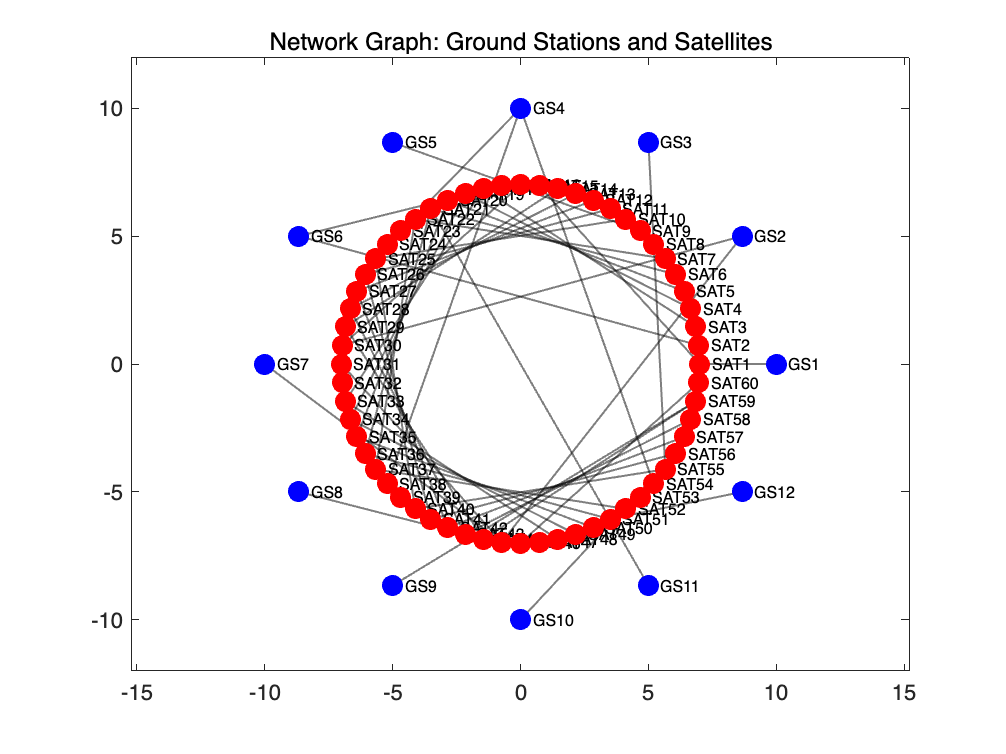

% Number of ground stations and satellites
num_ground_stations = length(receiving_gs_info(:,1));
num_satellites = length(list_of_Satellites);

% Create the node position;
ground_station_radius = 10; % Radius of the small circle for ground stations
satellite_radius = 7; % Radius of the outer circle for satellites

% Ground station positions
ground_station_angles = linspace(0, 2* pi, num_ground_stations+1);
ground_station_angles = ground_station_angles(1:end-1);
ground_station_x = ground_station_radius * cos(ground_station_angles);
ground_station_y = ground_station_radius * sin(ground_station_angles);

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_satellites+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Combine the node positions
x = [ground_station_x, satellite_x];
y = [ground_station_y, satellite_y];

% Plot the network graph
figure;
plot(G, 'XData', x, 'YData', y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', 'k', 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(ground_station_x, ground_station_y, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');